**Results of offline version on S1 and S2 datasets, as shown in Figure 8(a) and 8(b) of the paper.**

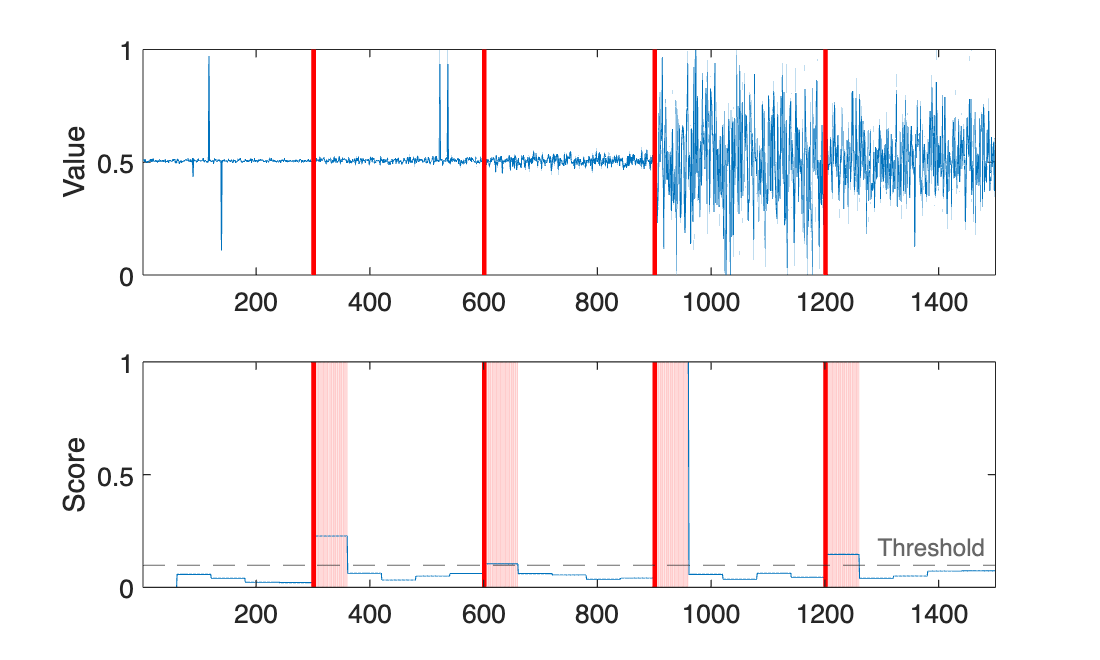

clear
load('S1.mat')
win_size = 60;
a = 0;

rng(3)
[best_Pscore, ~, ~ ] = best_psi(Y, win_size);
[b_threshold, result] = best_threshold(best_Pscore, a);

figure('Position',[100 100 500 300])

co=[0.00,0.45,0.74];
subplot(2, 1, 1)
plot(Y)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
ylabel('Value')

set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2)
hold on
plot(best_Pscore, 'Color',co)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
yline(b_threshold, '--','Threshold')
ylabel('Score')
 
set(gcf,'color','w');
set(gca,'FontSize',12);

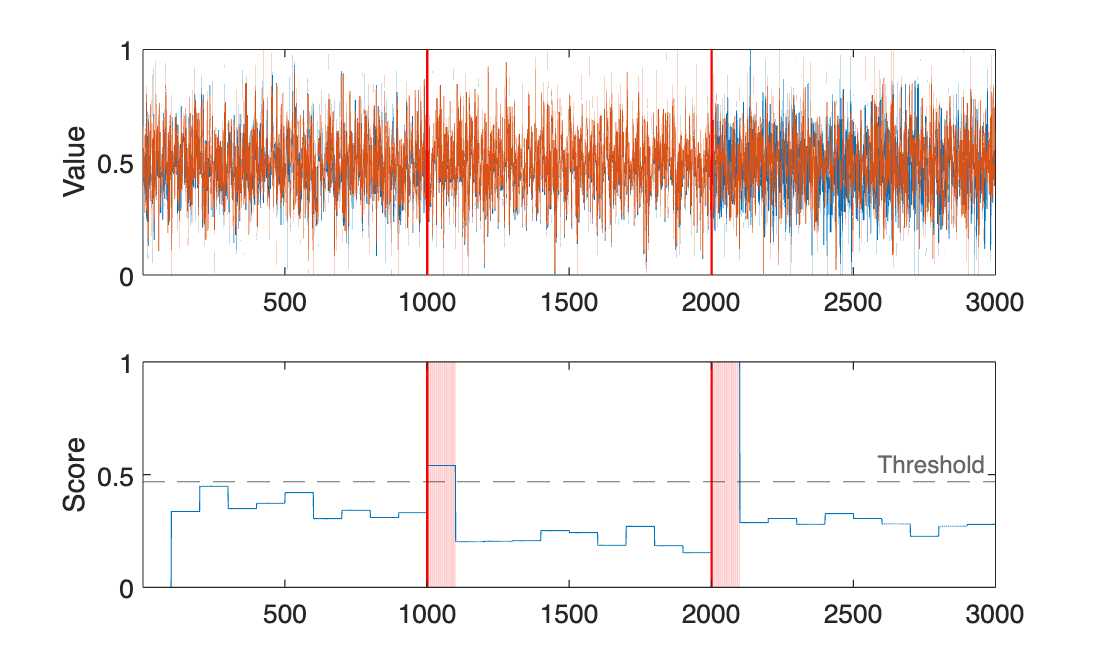

clear
load('S2.mat')
win_size = 100;
a = 1;

[best_Pscore, ~, ~ ] = best_psi(Y, win_size);
[b_threshold, result] = best_threshold(best_Pscore, a);

figure('Position',[100 100 500 300])

co=[0.00,0.45,0.74];
subplot(2, 1, 1)
plot(Y)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
ylabel('Value')

set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2)
hold on
plot(best_Pscore, 'Color',co)
hold on
bar(L, 'red','BarWidth',8)
xlim([1 length(best_Pscore)])
yline(b_threshold, '--','Threshold')
ylabel('Score')
 
set(gcf,'color','w');
set(gca,'FontSize',12);

**Results of online version on S1 and S2 datasets, as shown in Figure 9(a) and 9(b) of the paper.**

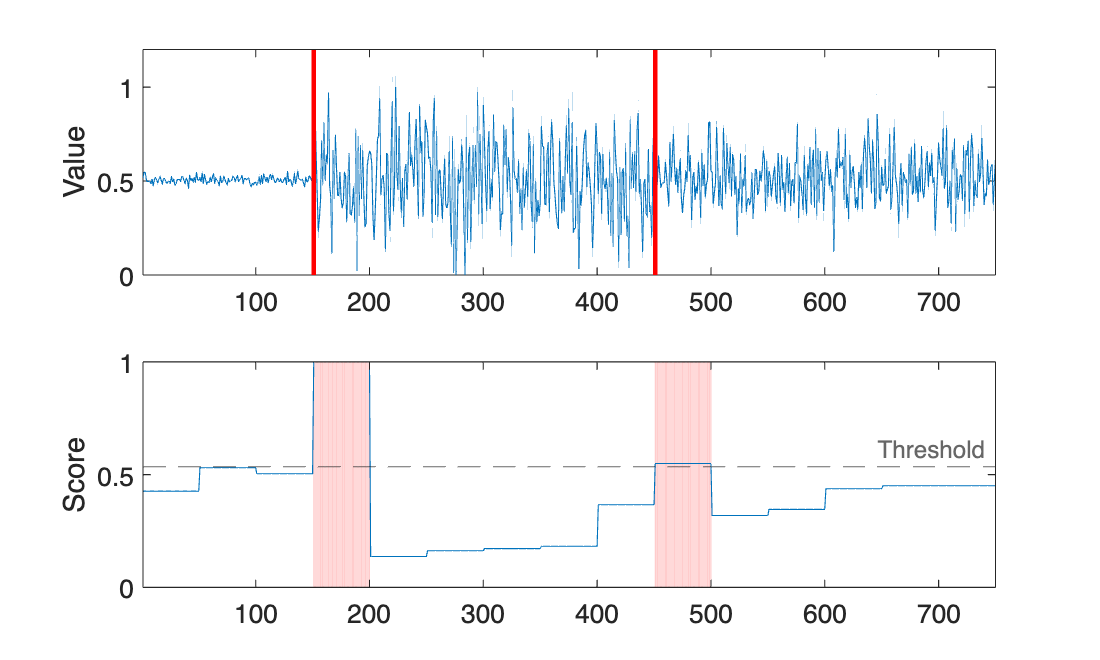

clear
load('S1.mat')
ratio = 0.5;
win_size = 50;
a = -0.35;

[trainset, testset, ~, testlabel] = datasetsplit(Y, L, ratio);
ref = length(trainset);

[best_Pscore, ~, b_psi ] = best_psi(trainset, win_size);
[b_threshold, ~] = best_threshold(best_Pscore, a);

score = [];
for i = 1 : win_size : length(Y)-ref+1
    rng(2)
    [best_Pscore] = point_score(Y(i:i+ref-1,:), b_psi, win_size);
    if i == 1
        score = [score; best_Pscore];
    else
        score = [score; best_Pscore(end-win_size+1:end)];
    end
end

if length(score) < length(Y)
    [best_Pscore] = point_score(Y(end-ref+1:end,:), b_psi, win_size);
    score = [score; best_Pscore(end-length(Y)+length(score)+1:end)];
end

score = score(ref+1:end);

result = score-score;
for i = 1:length(score)
    if b_threshold < score(i)
        result(i) = 1;
    else
        result(i) = 0;
    end
end


figure('Position',[100 100 500 300])
subplot(2, 1, 1)
plot(testset)
hold on
bar(testlabel*3, 'red','BarWidth',4) %4


xlim([1 length(score)])
ylabel('Value')
ylim([0 1.2])
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

co=[0.00,0.45,0.74];

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2,'EdgeColor','none') %0.2
hold on
plot(score, 'Color',co)
xlim([1 length(score)])
yline(b_threshold, '--','Threshold')
ylabel('Score') 
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);

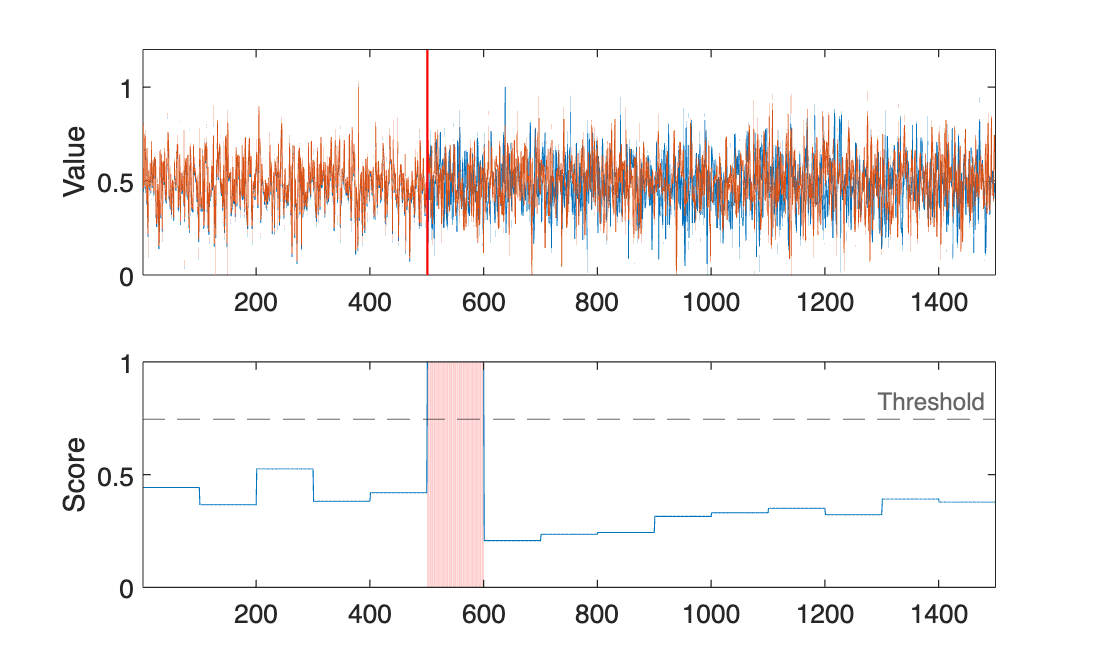

clear
load('S2.mat')
ratio = 0.5;

[trainset, testset, trainlabel, testlabel] = datasetsplit(Y, L, ratio);
ref = length(trainset);
win_size =100;
a = 1;

[best_Pscore, best_ent, b_psi ] = best_psi(trainset, win_size);
[b_threshold, ~] = best_threshold(best_Pscore, a);

score = [];

for i = 1 : win_size : length(Y)-ref+1
    [best_Pscore] = point_score(Y(i:i+ref-1,:), b_psi, win_size);
    if i == 1
        score = [score; best_Pscore];
    else
        score = [score; best_Pscore(end-win_size+1:end)];
    end
end

if length(score) < length(Y)
    [best_Pscore] = point_score(Y(end-ref+1:end,:), b_psi, win_size);
    score = [score; best_Pscore(end-length(Y)+length(score)+1:end)];
end

score = score(ref+1:end);

result = score-score;
for i = 1:length(score)
    if b_threshold < score(i)
        result(i) = 1;
    else
        result(i) = 0;
    end
end


figure('Position',[100 100 500 300])
subplot(2, 1, 1)
plot(testset)
hold on
bar(testlabel*3, 'red','BarWidth',4) %4


xlim([1 length(score)])
ylabel('Value')
ylim([0 1.2])
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);
set(gcf,'color','w');

co=[0.00,0.45,0.74];

subplot(2, 1, 2)
bar(result, 'red','FaceAlpha',0.2,'EdgeColor','none') %0.2
hold on
plot(score, 'Color',co)
xlim([1 length(score)])
yline(b_threshold, '--','Threshold')
ylabel('Score') 
set(gcf,'color','w');
set(gca,'LooseInset',get(gca,'TightInset'))
set(gca,'FontSize',12);